# Introduction to MATLAB - Hands-On Workshop

Today, we will discuss how we can use MATLAB and its features to aid in data analysis. Using these features, we can manage our code better, spend more time on the actual data analysis, and improve the entire development process.

In this example, we will analyze data we gathered from a quadcopter simulation executed in Simulink. Quadcopters are notoriously difficult environments for collecting good sensor data. Quadcopters typically have on-board IMU sensors, comprised of 3 gyroscopes and 3 accelerometers. Any type of autonomous flight requires using this sensor data to estimate a full state (position, velocity, Euler angles, angular rates). This difficulty of this task increases greatly if the sensor data is noisy.

Unfortunately, most quadcopters rely on low-cost sensors due to their affordability, which tend to exhibit higher levels of noise compared to the more expensive sensors used in the aviation industry. Furthermore, the quadcopter's airframe itself exacerbates the issue of sensor noise. The presence of 4 motors rotating 4 propellers at very high RPM (up to 30,000 RPM in this example) generates vibrations in the airframe that can contaminate the sensor data.

The objective of this flight test data analysis is to examine the IMU data and determine the characteristics of the sensor noise for implementing a Kalman filter sensor fusion algorithm. It is crucial to separate the sensor noise from the airframe vibration in the data to achieve accurate results.

## Part 0: Live Scripts

Let us explore this document. This .mlx file is a [Live Script](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html). Live Scripts are interactive documents that combine MATLAB code with formatted text, equations, and images in a single environment called the Live Editor. Let's try recreating the image of the equation below:

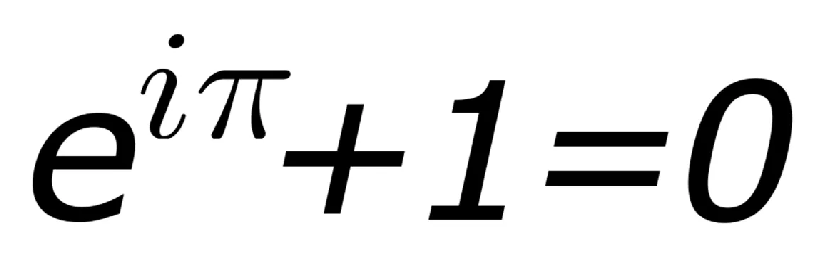

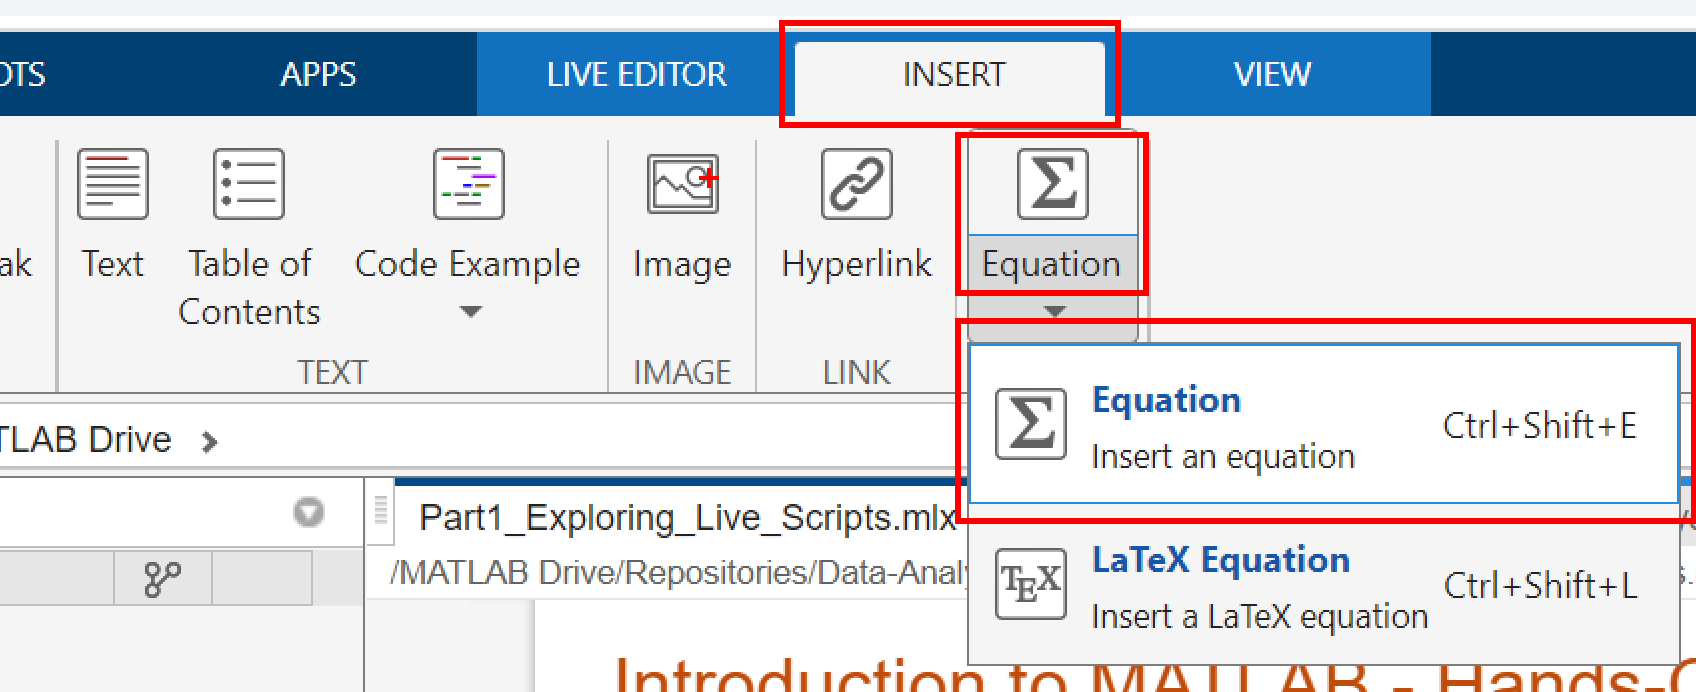

Written Equation: 

We can also use Live Scripts to: 

- Easily build reports

- Utilize unique features like [live controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) and [live tasks](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html) in th "Live Editor" toolstrip

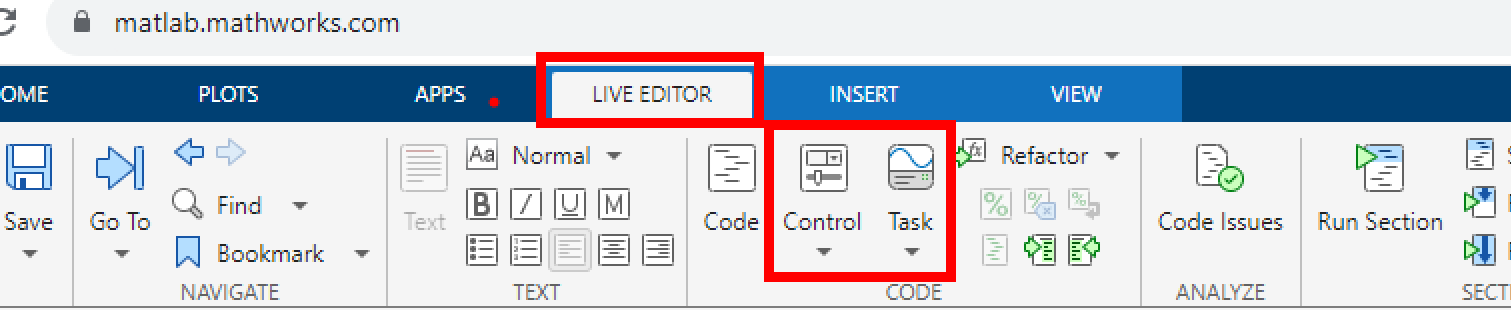

if false
    disp("I have been checked")
end

tempData = randi(1000,100,1);

- Interact with your data and plots more intuitively in the "Figure" toolstrip

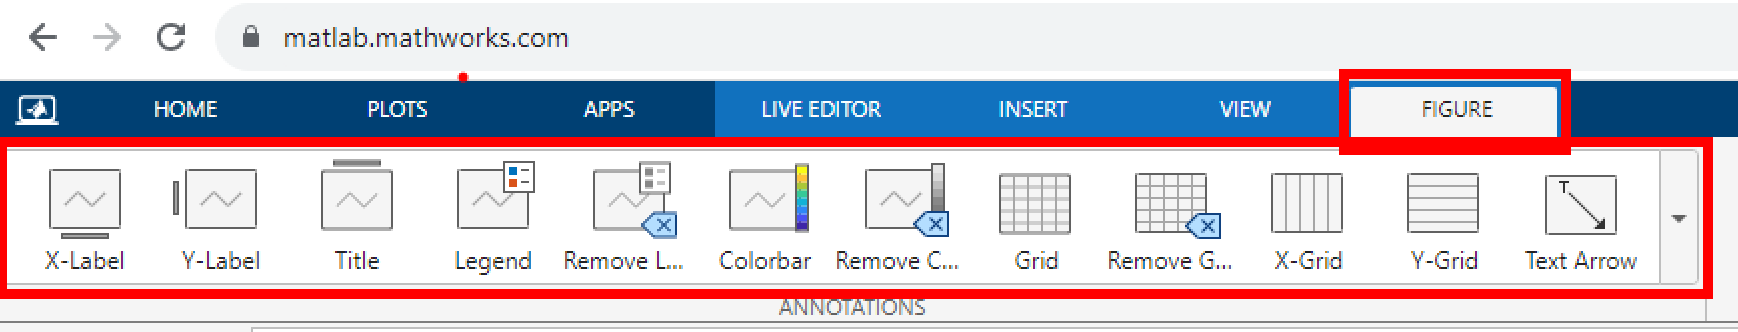

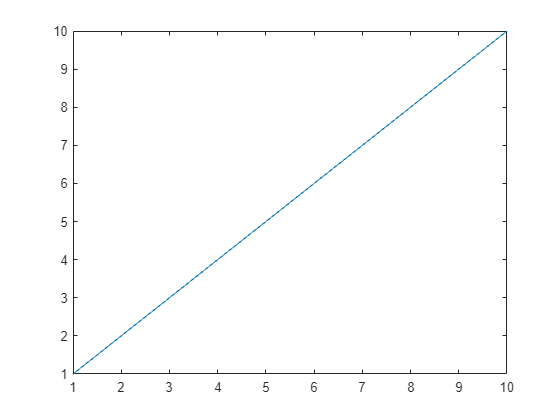

plot(1:10)

clear tempData